clear all

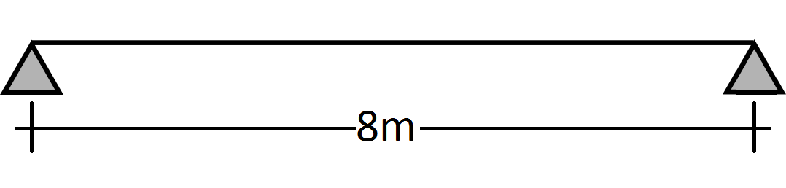

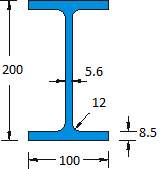

We consider a 30 metres long IPE200 beam

We define the physical properties of the beam:

L=8;          %m
E=200e9;       %N/m^2
I=1.9430e-05;   %m^4
m=22.4;        %Kg/m

EI=E*I;

We investigate the frequency range from 0 to 20 Hz

f=linspace(0,300,100000)

f =          0    0.0030    0.0060    0.0090    0.0120    0.0150    0.0180    0.0210    0.0240    0.0270    0.0300    0.0330    0.0360    0.0390    0.0420    0.0450    0.0480    0.0510    0.0540    0.0570    0.0600    0.0630    0.0660    0.0690    0.0720    0.0750    0.0780    0.0810    0.0840    0.0870    0.0900    0.0930    0.0960    0.0990    0.1020    0.1050    0.1080    0.1110    0.1140    0.1170    0.1200    0.1230    0.1260    0.1290    0.1320    0.1350    0.1380    0.1410    0.1440    0.1470


omega=2*pi*f;



$$\gamma=\sqrt[4]{\frac{m}{EI}}\sqrt{\omega}$$


gamma=(m/EI)^(1/4)*omega.^(1/2)

gamma =          0    0.0067    0.0095    0.0117    0.0135    0.0150    0.0165    0.0178    0.0190    0.0202    0.0213    0.0223    0.0233    0.0243    0.0252    0.0261    0.0269    0.0277    0.0285    0.0293    0.0301    0.0308    0.0316    0.0323    0.0330    0.0336    0.0343    0.0350    0.0356    0.0362    0.0368    0.0375    0.0381    0.0386    0.0392    0.0398    0.0404    0.0409    0.0415    0.0420    0.0425    0.0431    0.0436    0.0441    0.0446    0.0451    0.0456    0.0461    0.0466    0.0471


We consider the usual domain equation:


$$w=\left[A \sin \left( \gamma x \right) +B\cos\left( \gamma x \right)+C\sinh\left( \gamma x \right)+D\cosh\left( \gamma x \right)\right]\cos\left(\omega t + \psi \right)$$


We need to impose the boundary conditions:

Null dispacement in the first pin


$$w|_0=0 \; \; \Rightarrow \;\;B+D=0$$


Null bending moment in the first pin


$$EI \frac{\partial^2w}{\partial x^2}|_0=0 \; \; \Rightarrow \;\;EI(-\gamma^2B+\gamma^2 D)=0$$



$$\Rightarrow \;\;-B+ D=0$$


Null dispacement in the second pin


$$w|_L=0 \;\;\Rightarrow\;\;A \sin ( \gamma L ) +B\cos( \gamma L )+C\sinh( \gamma L )+D\cosh( \gamma L ) =0$$


Null bending moment in the second pin


$$EI w|_L=0 \;\;\Rightarrow\;\;-\gamma^2A \sin ( \gamma L ) -\gamma^2B\cos( \gamma L )+\gamma^2C\sinh( \gamma L )+\gamma^2D\cosh( \gamma L ) =0$$



$$\Rightarrow\;\;-A \sin ( \gamma L ) -B\cos( \gamma L )+C\sinh( \gamma L )+D\cosh( \gamma L ) =0$$


We can write the system BC matrix:


$$\pmatrix{
0 & 1 & 0 & 1 \cr
 0 & -1 & 0 & 1 \cr
 \sin(\gamma L) & \cos(\gamma L) & \sinh(\gamma L) & \cosh(\gamma L) \cr
 -\sin(\gamma L) & -\cos(\gamma L) & \sinh(\gamma L) & \cosh(\gamma L)}
$$
 

H=@(gamma) [  0             1            0             1            ;
    0            -1            0             1            ;
    sin(gamma*L)  cos(gamma*L) sinh(gamma*L) cosh(gamma*L);
    -sin(gamma*L) -cos(gamma*L) sinh(gamma*L) cosh(gamma*L)];

We obtain a 4 x 4 x 50 matrix containing the matrix H for each value of gamma.

We are looking for the value of gama for which the determinant of H is equal to zero

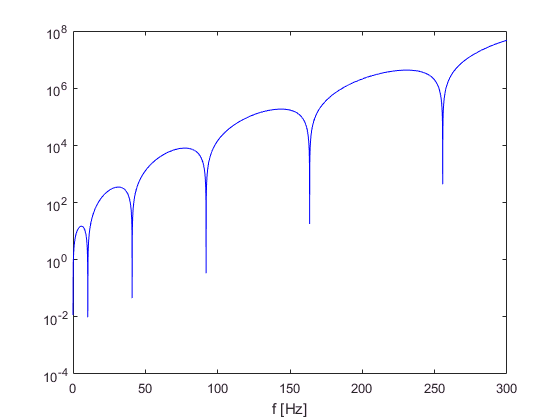

for i=1:length(gamma);
    dets(i)=det(H(gamma(i)));
end

semilogy(f,abs(dets),'-b')
hold on, xlabel('f [Hz]')

I have five values of f for which the determinant is (close) to zero

i_nat=[];
for i=2:length(dets)-1
    if abs(dets(i)) < abs(dets(i-1)) && abs(dets(i)) < abs(dets(i+1))
        i_nat(end+1)=i;
    end
end

fprintf('Natural frequencies:\n %f\n%f\n%f\n%f\n%f\n',f(i_nat))

Natural frequencies:
 10.224102
40.890409
92.004920
163.564636
255.569556


fprintf('Gamma:\n %f\n%f\n%f\n%f\n%f\n',gamma(i_nat))

Gamma:
 0.392725
0.785393
1.178099
1.570800
1.963500


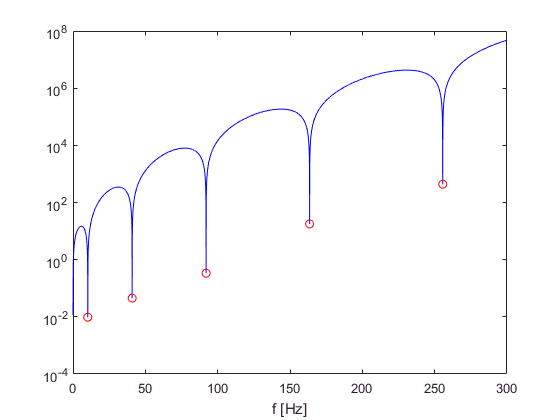

plot(f(i_nat),abs(dets(i_nat)),'or')

Now that we know the value for which the system is singular (i.e. admits non-trivial solutions), we can find the modal shapes solving the **reduced system:**


$$\left[ 
\matrix{
-&- \cr
\hat{E_i} & \hat{H}(\gamma_i)&
}
\right]
\left\{
\matrix{
1 \cr \hat{C_i} 
} 
\right\}

= 0$$



$$\hat{C_i}= -\hat{H}^{-1}(\gamma_i) \hat{E_i}$$


for i_mode=1:length(i_nat)
    fprintf('MODO %i',i_mode)
    gamma_i=gamma(i_nat(i_mode));
    Hi=H(gamma_i)
    Hi_hat=Hi(2:4,2:4)
    Ei_hat=Hi(2:4,1)
    Ci_hat=[1; -Hi_hat\Ei_hat]
    
    C_hat(:,i_mode)=Ci_hat;
end

MODO 1

Hi =          0    1.0000         0    1.0000
         0   -1.0000         0    1.0000
   -0.0002   -1.0000   11.5512   11.5944
    0.0002    1.0000   11.5512   11.5944


Hi_hat =    -1.0000         0    1.0000
   -1.0000   11.5512   11.5944
    1.0000   11.5512   11.5944


Ei_hat =    1.0e-03 *

         0
   -0.2094
    0.2094


Ci_hat =     1.0000
   -0.0002
    0.0002
   -0.0002


MODO 2

Hi =          0    1.0000         0    1.0000
         0   -1.0000         0    1.0000
   -0.0000    1.0000  267.7336  267.7355
    0.0000   -1.0000  267.7336  267.7355


Hi_hat =    -1.0000         0    1.0000
    1.0000  267.7336  267.7355
   -1.0000  267.7336  267.7355


Ei_hat =    1.0e-04 *

         0
   -0.4217
    0.4217


Ci_hat =     1.0000
    0.0000
   -0.0000
    0.0000


MODO 3

Hi =    1.0e+03 *

         0    0.0010         0    0.0010
         0   -0.0010         0    0.0010
   -0.0000   -0.0010    6.1959    6.1959
    0.0000    0.0010    6.1959    6.1959


Hi_hat =    1.0e+03 *

   -0.0010         0    0.0010
   -0.0010    6.1959    6.1959
    0.0010    6.1959    6.1959


Ei_hat =    1.0e-04 *

         0
   -0.1357
    0.1357


Ci_hat =     1.0000
   -0.0000
    0.0000
   -0.0000


MODO 4

Hi =    1.0e+05 *

         0    0.0000         0    0.0000
         0   -0.0000         0    0.0000
    0.0000    0.0000    1.4338    1.4338
   -0.0000   -0.0000    1.4338    1.4338


Hi_hat =    1.0e+05 *

   -0.0000         0    0.0000
    0.0000    1.4338    1.4338
   -0.0000    1.4338    1.4338


Ei_hat =    1.0e-04 *

         0
    0.3090
   -0.3090


Ci_hat =     1.0000
   -0.0000
    0.0000
   -0.0000


MODO 5

Hi =    1.0e+06 *

         0    0.0000         0    0.0000
         0   -0.0000         0    0.0000
   -0.0000   -0.0000    3.3179    3.3179
    0.0000    0.0000    3.3179    3.3179


Hi_hat =    1.0e+06 *

   -0.0000         0    0.0000
   -0.0000    3.3179    3.3179
    0.0000    3.3179    3.3179


Ei_hat =    1.0e-04 *

         0
   -0.3286
    0.3286


Ci_hat =     1.0000
   -0.0000
    0.0000
   -0.0000


C_hat

C_hat =     1.0000    1.0000    1.0000    1.0000    1.0000
   -0.0002    0.0000   -0.0000   -0.0000   -0.0000
    0.0002   -0.0000    0.0000    0.0000    0.0000
   -0.0002    0.0000   -0.0000   -0.0000   -0.0000


We can now compute the mode shapes


$$\phi_i(x)=\left[A \sin \left( \gamma_i x \right) +B\cos\left( \gamma_i x \right)+C\sinh\left( \gamma_i x \right)+D\cosh\left( \gamma_i x \right)\right]$$


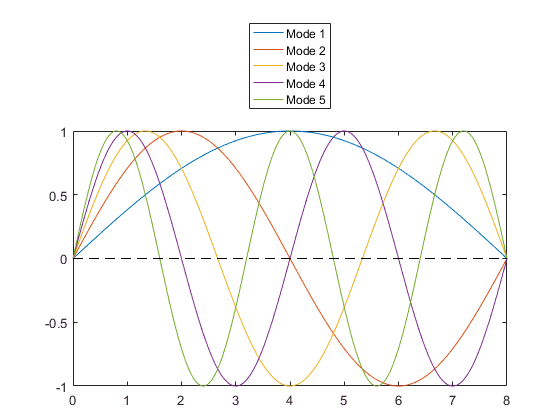


x=linspace(0,L,1000);
dx=x(2);
for i_mode=1:length(i_nat)
    gamma_i=gamma(i_nat(i_mode));
    phi(i_mode,:)= C_hat(1,i_mode)*sin(gamma_i*x)  + C_hat(2,i_mode)*cos(gamma_i*x) +...
        C_hat(3,i_mode)*sinh(gamma_i*x) + C_hat(4,i_mode)*cosh(gamma_i*x);
end

figure
plot(x,phi)
hold on, plot([0 L],[0 0],'--k')
ylim([-1 1])
legend({'Mode 1','Mode 2','Mode 3','Mode 4','Mode 5'},'Location','NorthOutside')

Now we can compute the energy functions using the Lagrange equation:


$$E_K= \frac{1}{2} \int_0^L m \frac{\partial w}{\partial t}\frac{\partial w}{\partial t} dx
=$$



$$=
\frac{1}{2} \dot{q}^T \int_0^L m \phi(x) \phi^T(x) \,dx \;\dot{q}
=$$



$$=
\frac{1}{2} \dot{q}^T [M] \;\dot{q}$$



$$\Rightarrow [M] =
 \int_0^L m \phi(x) \phi^T(x) \,dx$$


M=m*phi*phi'*dx

M =    89.5821   -0.0131   -0.0080   -0.0060   -0.0048
   -0.0131   89.6018    0.0022    0.0014    0.0010
   -0.0080    0.0022   89.5996   -0.0000   -0.0002
   -0.0060    0.0014   -0.0000   89.5993   -0.0005
   -0.0048    0.0010   -0.0002   -0.0005   89.5994


As you can see **M is diagonal**


$$V= \frac{1}{2} \int_0^L EJ \frac{\partial^2 w}{\partial x^2}\frac{\partial^2 w}{\partial x^2} dx
=$$



$$=
\frac{1}{2} q^T \int_0^L EJ \phi''(x) \phi''^T(x) \,dx \;q
=$$



$$=
\frac{1}{2} q^T [K] \;q$$



$$\Rightarrow [K] =
 \int_0^L EJ \phi''(x) \phi''^T(x) \,dx$$


phi2=diff(phi,2,2)/(dx^2);

K=EI*phi2*phi2'*dx

K =    1.0e+08 *

    0.0037   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0591    0.0000    0.0000    0.0000
   -0.0000    0.0000    0.2994    0.0000    0.0000
   -0.0000    0.0000    0.0000    0.9463    0.0000
   -0.0000    0.0000    0.0000    0.0000    2.3103


**As you can see K is diagonal too!**

**The equation of motion for this system is therefore:**


$$[M]\ddot{q} + [K]\dot{q} = 0$$


Now consider the same beam, this time with a damper in the middle:

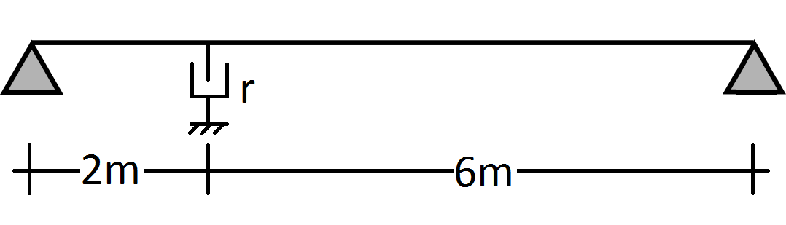

We need to compute the damping function.

We say that:


$$D =\frac{1}{2} r \frac{\partial w}{\partial t}|_{x=2} \frac{\partial w}{\partial t}|_{x=2}=$$



$$= \frac{1}{2} \dot{q}^T r \phi(x=2)\phi^T(x=2)\dot{q}=$$



$$= \frac{1}{2} \;\dot{q}^T [C]\;\dot{q}
$$



$$\Rightarrow\; [C]=r\,\phi(x=2)\,\phi^T(x=2)$$


xDamper=2;
r=.10 * 2 * M(1,1) * omega(i_nat(1));

[~,i_damper]=min(abs(x-xDamper));
phi_damper=phi(:,i_damper)

phi_damper =     0.7075
    1.0000
    0.7054
   -0.0031
   -0.7099


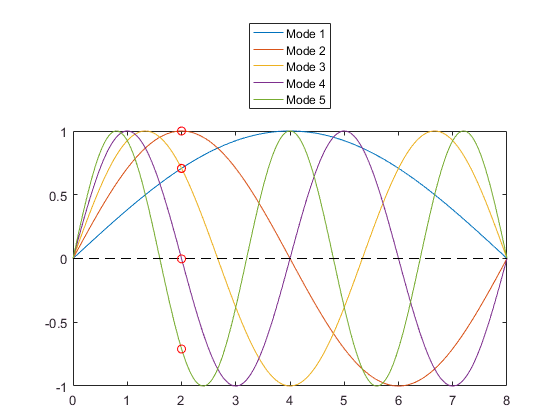


plot(xDamper,phi_damper,'or')


R=r*phi_damper*phi_damper'*dx

R =    1.0e+03 *

    4.6130    6.5205    4.5998   -0.0204   -4.6287
    6.5205    9.2170    6.5020   -0.0288   -6.5427
    4.5998    6.5020    4.5867   -0.0203   -4.6155
   -0.0204   -0.0288   -0.0203    0.0001    0.0204
   -4.6287   -6.5427   -4.6155    0.0204    4.6444


**R IS NOT DIAGONAL!!**

We want to compute the eigenvalues and eigenvectors of the damped system.

We use the the system state variable


$$z=\left\{ \matrix{ \dot{q} \cr q } \right\}$$


to write the system as


$$\matrix{[M] \ddot{q} & +  [R]\dot{q} & +  [K]q &=0 \cr
[M]\dot{q} && -[M]\dot{q} &=0}$$


that allow the system to be written as


$$\left[ \matrix{ 
[M] & [0] \cr
[0] & [M]
} \right]
\left\{ \matrix{
\ddot{q} \cr
\dot{q}
} \right\}

+

\left[ \matrix{ 
[R] & [K] \cr
-[M] & [0]
} \right]
\left\{ \matrix{
\dot{q} \cr
q
} \right\}

=
\left\{ \matrix{
0 \cr
0
} \right\}$$



$$[B]\dot{z} + [C]z=0$$



$$[A] = -[B]^{-1}[C]$$



$$\dot{z}-[A]z=0$$


B=[M,              zeros(size(M));
    zeros(size(M)), M             ];
C=[ R, K             ;
    -M, zeros(size(M))];
A=-inv(B)*C;

we can use this equation to write the eigenvalue problem


$$[[A] -\lambda[I]]Z=0$$



[phi_damped,lamba_damped]=eig(A,'vector')

phi_damped =    0.0038 - 0.0318i   0.0038 + 0.0318i  -0.0222 + 0.0844i  -0.0222 - 0.0844i   0.9965 + 0.0000i   0.9965 + 0.0000i   0.0193 + 0.3128i   0.0193 - 0.3128i   0.0001 - 0.0002i   0.0001 + 0.0002i
   0.0054 - 0.0460i   0.0054 + 0.0460i  -0.0360 + 0.1483i  -0.0360 - 0.1483i   0.0299 - 0.0763i   0.0299 + 0.0763i   0.9474 + 0.0000i   0.9474 + 0.0000i   0.0000 - 0.0003i   0.0000 + 0.0003i
   0.0042 - 0.0364i   0.0042 + 0.0364i   0.9843 + 0.0000i   0.9843 + 0.0000i   0.0036 - 0.0104i   0.0036 + 0.0104i   0.0294 - 0.0571i   0.0294 + 0.0571i   0.0001 - 0.0003i   0.0001 + 0.0003i
  -0.0000 + 0.0002i  -0.0000 - 0.0002i  -0.0001 + 0.0002i  -0.0001 - 0.0002i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0001i  -0.0000 - 0.0001i   1.0000 + 0.0000i   1.0000 + 0.0000i
   0.9977 + 0.0000i   0.9977 + 0.0000i  -0.0043 + 0.0117i  -0.0043 - 0.0117i  -0.0004 + 0.0014i  -0.0004 - 0.0014i  -0.0028 + 0.0066i  -0.0028 - 0.0066i   0.0000 - 0.0001i   0.0000 + 0.0001i
  -0.0000 - 0.0000i  -0.0000 + 0

lamba_damped =    1.0e+03 *

  -0.0255 + 1.6021i
  -0.0255 - 1.6021i
  -0.0235 + 0.5703i
  -0.0235 - 0.5703i
  -0.0284 + 0.0615i
  -0.0284 - 0.0615i
  -0.0514 + 0.2419i
  -0.0514 - 0.2419i
  -0.0000 + 1.0277i
  -0.0000 - 1.0277i


We have 10 eigen-vectors and 10 eigen-values complex coniugated two by two. We keep only one of each

phi_damped=phi_damped(:,1:2:end);
lamba_damped=lamba_damped(1:2:end);

Since we are interested only in the first 5 lines of the previous system, we keep only the first 5 values of each eigen-vector

phi_damped=phi_damped(1:5,:);

Now we sort the eigen-values smallest-to-biggest and the eigen-vectors accordingly.

[lamba_damped,sortInd]=sort(lamba_damped);
phi_damped=phi_damped(:,sortInd)

phi_damped =    0.9965 + 0.0000i   0.0193 + 0.3128i  -0.0222 + 0.0844i   0.0001 - 0.0002i   0.0038 - 0.0318i
   0.0299 - 0.0763i   0.9474 + 0.0000i  -0.0360 + 0.1483i   0.0000 - 0.0003i   0.0054 - 0.0460i
   0.0036 - 0.0104i   0.0294 - 0.0571i   0.9843 + 0.0000i   0.0001 - 0.0003i   0.0042 - 0.0364i
  -0.0000 + 0.0000i  -0.0000 + 0.0001i  -0.0001 + 0.0002i   1.0000 + 0.0000i  -0.0000 + 0.0002i
  -0.0004 + 0.0014i  -0.0028 + 0.0066i  -0.0043 + 0.0117i   0.0000 - 0.0001i   0.9977 + 0.0000i


We can plot these eigen-vetors in the complex plane:

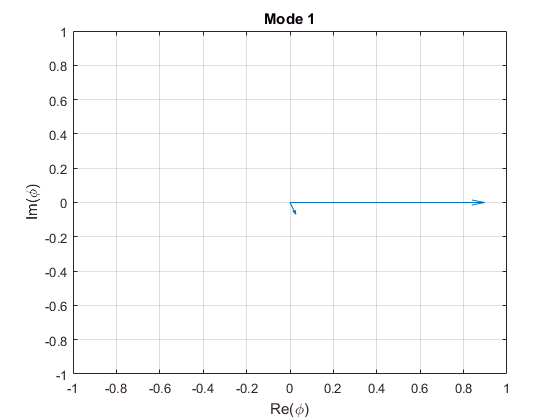

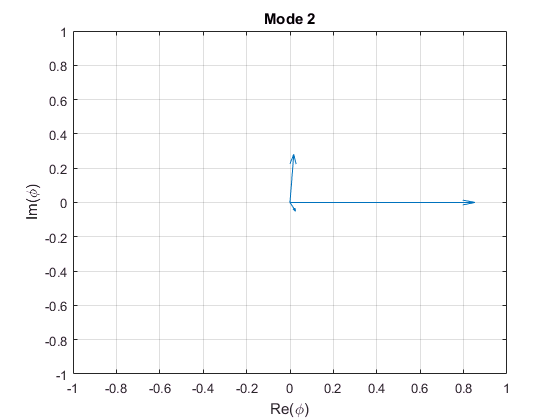

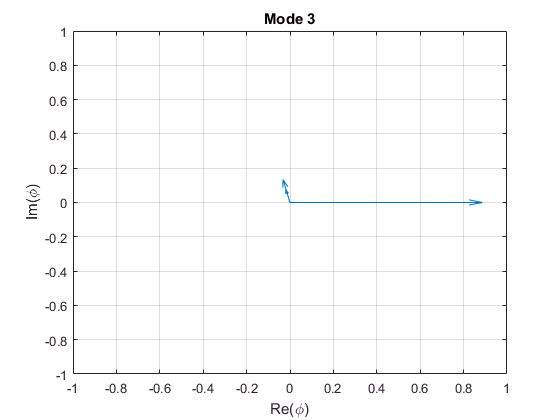

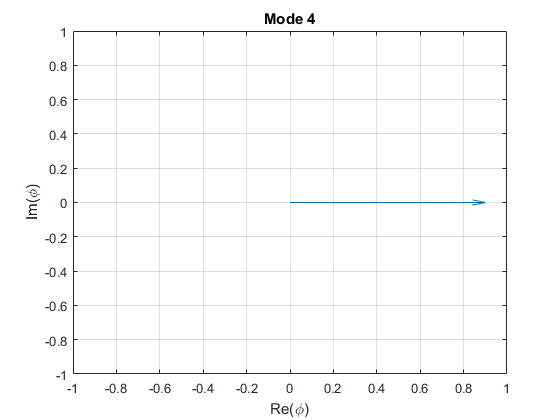

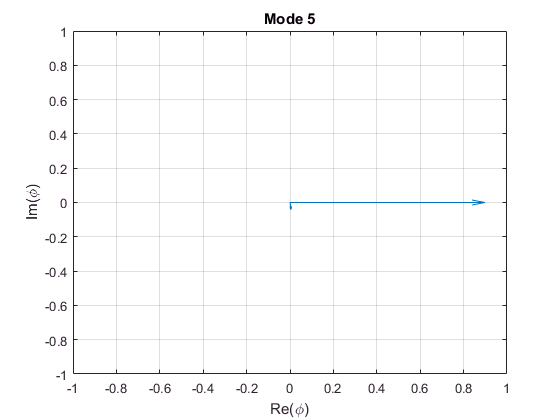

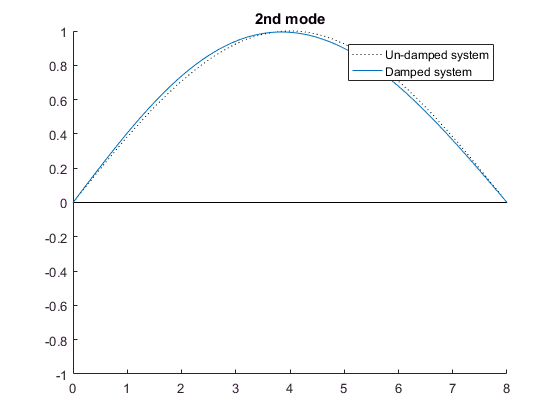

for i=1:5
    figure
    quiver(zeros(5,1),zeros(5,1),real(phi_damped(:,i)),imag(phi_damped(:,i)))
    title(sprintf('Mode %i',i))
    xlim([-1 1]), ylim([-1 1])
    xlabel('Re(\phi)'), ylabel('Im(\phi)')
    grid on
end

Consider Mode 2:

The damped mode will be:


$$w_2(x,t)=\phi(x)^T \phi_{D,2} \;q(t) = \phi(x)^T \phi_{D,2} \;e^{i\omega_1 t}$$


since $\phi_{D,2}$ is complex, also the vibrating mode will be complex, with some components out of phase with respect to the "pure" mode. To look at it we need to see it in the time domain:

(run modeAnimation.m)